% image class network
imds = imageDatastore("DigitDataset", "IncludeSubfolders",true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\DigitDataset\0\image10000.png';
                              ' ...\DigitDataset\0\image9001.png';
                              ' ...\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\Assignment 3.1 Image classification network\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



[train, valid] = splitEachLabel(imds, 0.75, "randomized");

imageSize = [28 28 1];
filterSize = 5;
numFilters = 20;
numClasses = 10;


layers =   [
            imageInputLayer(imageSize) 
            convolution2dLayer(filterSize, numFilters)
            batchNormalizationLayer
            reluLayer
            fullyConnectedLayer(numClasses)
            softmaxLayer
            classificationLayer
            ]

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5×5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex


opts = trainingOptions("sgdm", ...
                        "InitialLearnRate",0.01, ...
                        "MaxEpochs",4, ...
                        "Shuffle","every-epoch", ...
                        "ValidationFrequency",30 ...
                        ,"Plots","training-progress", ...
                        "Verbose", false, ...
                        "ValidationData",valid)

opts =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 0.0100
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 4
               MiniBatchSize: 128
                     Verbose: 0
            VerboseFrequency: 50
              ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
         ValidationFrequency: 30
          ValidationPatience: Inf
                     Shuffle: 'every-epoch'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
  



[DigitNet, info] = trainNetwork(train,layers,opts);



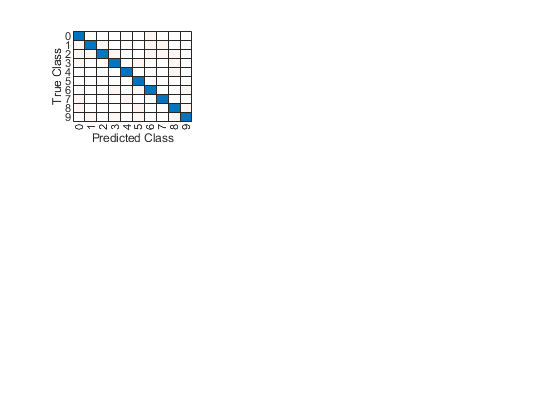


testpreds = classify(DigitNet, valid);

digitActual = valid.Labels;
confusionchart(digitActual, testpreds)

numCorrect = nnz(testpreds == digitActual);
fracCorrect = numCorrect/2500

fracCorrect = 0.9868

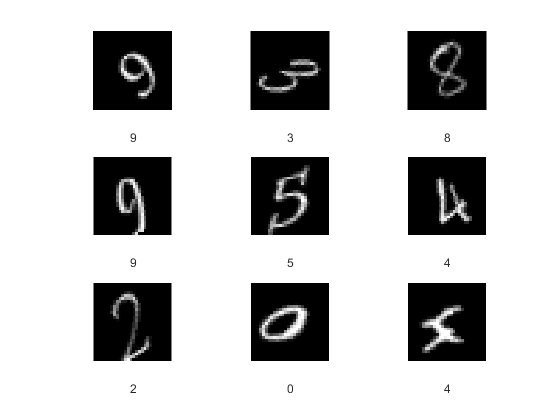



 % Vet ej hur subplotten ska vara
figure;
perm = randperm(2500,9);
for i = 1:9
 subplot(3,3,i)
 imshow(valid.Files{perm(i)})
 xlabel(testpreds(perm(i)))

 
end